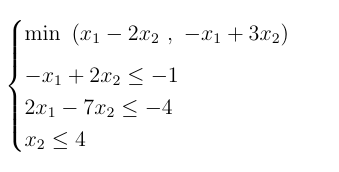

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

**a) Is it a convex problem? Why?**

Yes, it is. Because the objective functions and the inequalities constraints are linear, which are convex sets.

f_1 = @(x1,x2) x1 - 2*x2;
f_2 = @(x1,x2) -x1 + 3*x2;
c_1 = @(x1,x2) 2*x1 - 7*x2 + 4;
c_2 = @(x1,x2) -x1 + 2*x2 + 1;
c_3 = @(x2) x2-4;

x1 = linspace(-30, 30, 100);
x2 = linspace(-30, 30, 100);

[X1,X2] = meshgrid(x1,x2);

%Objective Functions
F1 = f_1(X1,X2);
F2 = f_2(X1,X2);
% Feasible region
C1 = c_1(X1,X2);
C2 = c_2(X1,X2);
C3 = c_3(X2);

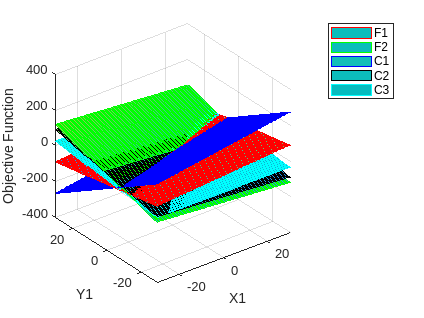

% 3D
figure;
surf(X1,X2,F1, "EdgeColor", "r");
hold on
surf(X1,X2,F2, "EdgeColor", "g");

surf(X1,X2,C1, "EdgeColor", "b");
surf(X1,X2,C2, "EdgeColor", "k");
surf(X1,X2,C3, "EdgeColor", "c");

xlabel('X1');
ylabel('Y1');
zlabel('Objective Function')

legend('F1', 'F2', 'C1', 'C2', 'C3');

hold off

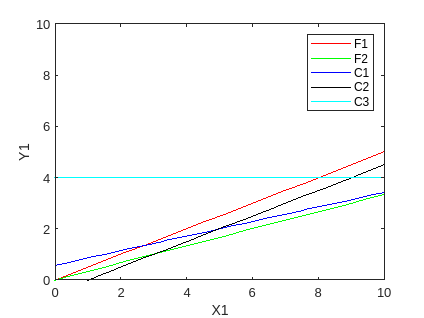

% 2D
figure;
contour(X1,X2,F1, [0 0], 'r');
hold on
contour(X1,X2,F2, [0 0], 'g');

contour(X1,X2,C1, [0 0], 'b');
contour(X1,X2,C2, [0 0], 'k');
contour(X1,X2,C3, [0 0], 'c');

xlabel('X1');
ylabel('Y1');

xlim([0 10]);
ylim([0 10]);

legend('F1', 'F2', 'C1', 'C2', 'C3');
hold off

**b) Do Pareto minima exist? Why?**

Yes, because the functions are continuos for any objective function and the feasible region is closed and bounded.

**c) Find all the Pareto minima by using the scalarization method.**

**d) Find all the weak Pareto minima by using the scalarization method.**

Using scalarization methods we got as unique objective function = 


$${f\left(x\right)\;=\;x}_1 \left(2\alpha -1\right)+x_2 \left(3-5\alpha \right)$$


A = [2 -7
    -1  2
     0  1];

b = [-4
     -1
      4];

i = 0.001:0.001:0.999;
x = zeros(size(i,2),2);
index = 1;

options = optimset('Display', 'off');

for alpha = i
    f = [2*alpha - 1
         -5*alpha + 3];
    solution = linprog(f',A,b, [],[],[],[],options);
    x(index,:) = solution(1:2);
    index = index + 1;
end


alpha = 1

alpha = 1

f = [2*alpha - 1
     -5*alpha + 3];
solution = linprog(f',A,b, [],[],[],[],options);
x1 = solution(1:2);


alpha = 0

alpha = 0

f = [2*alpha - 1
     -5*alpha + 3];
solution = linprog(f',A,b, [],[],[],[],options);
x0 = solution(1:2);

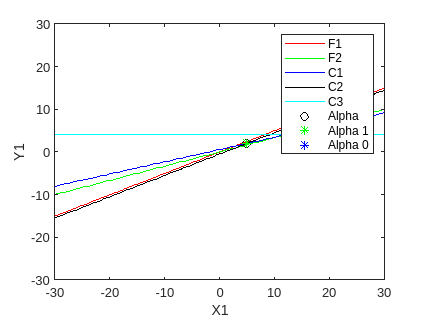

figure;
contour(X1,X2,F1, [0 0], 'r');
hold on
contour(X1,X2,F2, [0 0], 'g');

contour(X1,X2,C1, [0 0], 'b');
contour(X1,X2,C2, [0 0], 'k');
contour(X1,X2,C3, [0 0], 'c');

xlabel('X1');
ylabel('Y1');

plot(x(:,1), x(:,2), 'ko');
plot(x1(1), x1(2), 'g*');
plot(x0(1), x0(2), 'b*');

legend('F1', 'F2', 'C1', 'C2', 'C3', 'Alpha', 'Alpha 1', 'Alpha 0');
hold off

**e) Find the ideal point and apply the goal method with L2 .**

The ideal point is:


$$z_i =\underset{x\;\epsilon \;X}{\min \;f_i \left(x\right)}$$


C = [1 -2
    -1  3];
[p,n] = size(C);
z = zeros(p,1);
for i = 1:p
    f = C(i,:)';
    [~, z(i)] = linprog(f,A,b, [],[],[],[],options);
end


disp(z);

    1.0000
    0.0000



L2 

H = C'*C;
f = C'*z;

solution = quadprog(H,f,A,b, [],[],[],[],[],options);

disp(solution(1:n));

    5.0000
    2.0000

